# Session 1: Segmenting Clients

## How to use this live script

In this executable notebook (Live Editor) you have a logical track of the work, with working code snippets, some method suggestions (absolutely non-binding).

Remember: when it comes to data modeling, there is almost never a "one size fits all", thus you can take various ways to solve the problem.

So feel free to take this code as a draft, change it, even significantly, following your modeling vision. Feel free to explore data and methods and gain experience (yes, even getting it wrong and getting results you don't like - it's quite normal in real applications). You will find some "*HINTS*": they are just suggestions for you.

Remember: experimenting with data - that's the purpose of this Machine Learning Lab.

## Goal

Here we have a random extraction of a dataset made up of a bank's customers. The data is anonymous, mostly clean and normalized in [0, 1].

We intend to segment these customers using Data Science techniques (essentially Unsupervised Machine Learning); this is a segmentation carried out from the perspective of the financial services sector.

The dataset is called "BankClients" and is conveniently saved as a .mat file, even if you have also the corresponding .xls file.

#### *Load data from Mac*

close all
clear all
clc
load('/Users/michelebersani/Desktop/Università_politecnico/MAGISTRALE/ANNO_1/SECONDO_SEM/FINTECH/LABORATORIO/BusinessCase1/BankClients.mat')

#### *Load data from PC Windows*

% load('C:\Users\raffaele\Dropbox (virtualb)\RaffaeleZenti\MyMatlab\Laboratorio_Politecnico_Milano\BankClients.mat')

### Summary and first data exploration

In the following section we'll do some specific data exploration, very focused on the clustering problem, as well as preparing the data for convenient manipulation.

*HINT*: You can explore your data using the **plot catalog**. (For good examples of plots see [https://it.mathworks.com/products/matlab/plot-gallery.html.)](https://it.mathworks.com/products/matlab/plot-gallery.html.))

### Preparing data

We extract the variables of interest, also dividing into:

- numerical;

- categorical (excluding the ID, which is not informative at this level).

We have to:

**encode** categorical variables, so that they can be digestible by clustering algorithms - they are all trasformed in boolean variables by the `dummyvar `hot encoding function ([https://it.mathworks.com/help/stats/dummyvar.html](https://it.mathworks.com/help/stats/dummyvar.html));

- **normalize** in [0, 1] numerical variables - we use the `rescale` function ([https://it.mathworks.com/help/matlab/ref/rescale.html](https://it.mathworks.com/help/matlab/ref/rescale.html)) function.

% Numerical
% Questa riga definisce un vettore logico N che contiene true per le colonne che sono di tipo numerico nel dataset BankClients. Si utilizza la funzione vartype() per ottenere questo vettore.
N = vartype('numeric');
% Questa riga crea una nuova tabella NumFeatures che contiene solo le colonne numeriche del dataset Data, utilizzando il vettore logico N come maschera.
Data = BankClients(:,2:end); % Exclude 1st col = ID
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables;
for i = 1:size(XNum,2)
    % riscala solo quelle numeriche
    XNum(:,i) = rescale(XNum(:,i)); % normalize in [0, 1], mostly unnecessary here (CHECK THIS)
end

% Categorical
% POSSONO ESSERE ATTRATTORI DI GRUPPI
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
% Il ciclo for successivo sembra creare le variabili dummy per le variabili categoriche usando dummyvar() e memorizzarle in una matrice XCat. Le variabili dummy sono create per codificare le variabili categoriche come variabili binarie (0 o 1),
% COSì POI DOPO POSSO FARE IL CALCOLO DELLA DISTANZA CON LE COORDINATE =>
% TIPO FARE MANAHATTAN
XCat = [];
for i = 1:size(CatFeatures, 2)
    % disp('ciclo: ');
    % disp(i);
    % disp('---');
    % disp(CatFeatures{:,i});
    % disp('XCat_i');
    
    % trasforma gli 1 -> (0,1) e 0 -> (1,0) permette di mapparla nello
    % se ho tipo 5 tipi mi da 5 coordinate
    % spazio per poi fare dopo la distanza
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    % disp(XCat_i);
    % disp('cancello');
    
    % indica che stiamo selezionando tutte le righe della matrice "XCat_i", ma stiamo selezionando solo le colonne dalla prima fino alla penultima colonna.
    % elimino una delle colonne perchè è ricavabile dalle altre => devo
    % avere colonne linearmente indipendenti
    
    % disp(XCat_i(:,1:end-1));
    % disp('---');
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
    % disp(XCat);
end

Let's put all the features together in a matrix and start doing clustering analysis.

X = [XCat XNum];
disp('La matrice è:');

La matrice è:


% disp(X);

#### A trick of a tail

We use a random subsample of the original dataset to avoid biblical computational times...

It's OK for quick exploratory/model selection analysis, even on differen small sub-samples; then, when you have a clearer modeling strategy, use a bigger sample to get more general results.

% Definisce il numero di righe che devono essere selezionate casualmente come sottoinsieme.
nSubSample = 1950;
rng('default') % for reproducibility
% Genera un vettore di indici casuali delle righe del set di dati X. La funzione randperm() genera una permutazione casuale degli indici delle righe da 1 a size(X, 1) (che è il numero di righe in X) e seleziona i primi nSubSample indici.
randRows = randperm(size(X, 1), nSubSample);
% Seleziona le righe corrispondenti agli indici generati casualmente dal vettore randRows e riassegna la matrice X in modo che contenga solo le righe selezionate.
% alla fine prende righe a caso
X = X(randRows', :);

## Unsupervised clustering with mixed categorical and continuous data

Standard clustering algorithms like k-means don’t work with categorical data - and we have to cope with categorical data...

The sample space for categorical data is discrete, and doesn't have a natural origin, so an Euclidean distance (L2) function on such a space isn't really meaningful. That is, the basic concept of k-means stands on mathematical calculations (means, euclidian distances). But what if our data is non-numerical or, in other words, *categorical*?

Let's understand the situation at a glance...

figure
scatter(BankClients.Age,BankClients.Gender)
title('Why categorical variables are a problem when you want to cluster data...')
ylabel('Gender (categorical, nominal)')
xlabel('Age (numerical, continuous')

There are variations of k-means known as k-modes and k-medoids suitable for categorical data.

We will use **k-medoids clustering**: it is a partitioning method commonly used in domains for which the mean or median does not have a clear definition, see [https://it.mathworks.com/help/stats/kmedoids.html.](https://it.mathworks.com/help/stats/kmedoids.html.)

The key ideas undelying k-medoids are the following:

- The algorithm is **similar to k-means but instead of means uses medoids** ([https://en.wikipedia.org/wiki/Medoid](https://en.wikipedia.org/wiki/Medoid)), a generalization of the same concept - key idea: you use actual data points instead of means;

- So, instead of using the vector of means, the **medoid** is the center of the cluster.

### Distance function

We cannot use the same distance metric for numerical and categorical features: we need a proper distance function.

So we can create a **custom distance metric** and function (MixDistance):

- for the categorical variables we use the **Hamming** **distance** (see  [https://en.wikipedia.org/wiki/Hamming_distance](https://en.wikipedia.org/wiki/Hamming_distance)), which is the percentage of coordinates that differ;

- for the numerical features we use the **L1 norm** (aka Manhattan, or City Block distance, see [https://en.wikipedia.org/wiki/Taxicab_geometry);](https://en.wikipedia.org/wiki/Taxicab_geometry);)

- we combine them using the relative weight of categorical/numerical variables.

### Some Data Exploration

Let's have a bird’s view of the characteristics of the dataset and the behaviour of different distance metrics.

Let's compare distance metrics using **t-SNE** ([https://it.mathworks.com/help/stats/t-sne.html](https://it.mathworks.com/help/stats/t-sne.html)), i.e., *t*-distributed Stochastic Neighbor Embedding: an algorithm for dimensionality reduction that is well-suited to visualizing high-dimensional data. The underlying idea is to embed high-dimensional points in low dimensions in a way that respects similarities between points, using specific distance metrics.

Basically, you visualize the low-dimensional points to see natural clusters in the original high-dimensional data.

We begin with 2-D t-SNE embedding.

% BISOGNO DI CREARE UNA NUOVA FUNZIONE DI DISTANZA PERCHè CATEGORIA DI COME
% GENDER SONO GIà DENTRO A DELLE CATEGORIE E QUINDI NON POSSIAMO USARE
% DISTANZA EUCLIDEA

% L'obiettivo è visualizzare i dati ad alta dimensionalità in una
% rappresentazione a bassa dimensionalità mantenendo le similarità tra i
% punti attrverso utilizzo di una funzione di distanza data come parametro
rng('default') % for reproducibility
% il codice esegue t-SNE per ridurre la dimensionalità del dataset X a 2 dimensioni. Utilizza l'algoritmo 'exact' per il calcolo esatto di t-SNE e specifica la distanza 'citybloc' come metrica di distanza.
Y = tsne(X,'Algorithm','exact','Distance','citybloc');
subplot(2,2,1)
gscatter(Y(:,1),Y(:,2))
title('City bloc')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','cosine');
subplot(2,2,2)
gscatter(Y(:,1),Y(:,2))
title('Cosine')

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','euclidean');
subplot(2,2,3)
gscatter(Y(:,1),Y(:,2))
title('Euclidean')

rng('default') % for fair comparison
% qui va a chiamare la funzione @MixDistance che mette assieme le distanza Hamming + Cityblock
% Quindi, le due matrici di input fornite alla funzione MixDistance rappresentano due insiemi di punti nel tuo spazio di dati. Ad esempio, se X è la matrice delle caratteristiche originali e Y è una copia di X, allora MixDistance(X, Y) calcolerà le distanze tra i punti in X e i punti in Y.
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance);
subplot(2,2,4)
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Cityblock')


% PER RAPPRESENTARE I DATI MULTIDIMENSIONALE IN UNO SPAZIO TRIDIMENSIONALE
% BISOGNA RIDURRE LE DIMENSIONI CON ALGORITMI DI SOLITO SI PERDE
% INFORMAZIONE

Now, Let's scale up and try a 3-D t-SNE embedding... 

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance,'NumDimensions',3);

     3

    18

    4.2209

     3

    18

  Columns 1 through 3.276

    4.2209    3.2488    4.7632    5.7063    4.6460    3.2475    6.5009    4.8932    5.3798    4.4013    6.3187    4.6615    3.6005    4.0223    6.2207    4.4300    4.9043    4.7710    4.1351    5.4207    4.5681    5.6924    2.8045    2.2673    5.9951    3.4554    2.6071    4.5573    6.2929    5.5204    4.3663    6.4410    7.0259    6.3480    6.5153    2.8208    5.7051    5.1054    5.2434    4.1612    5.4048    4.2072    4.2028    6.3709    4.9450    3.9173    6.5572    4.3056    5.1992    4.3738    5.5043    3.3021    6.4110    3.6332    3.8199    5.1989    5.7515    3.8532    1.9784    3.1006    6.7517    5.1134    6.1332    5.1349    3.8606    5.4910    4.5863    1.9120    7.5004    5.3473    5.4928    4.3193    5.4664    5.6831    4.8660    3.9146    5.1225    5.2005    6.1271    4.9777    5.6144    6.9899    4.5605    3.7068    3.8215    6.1816    5.4134    4.3707    6.2061    4.9251    4.3611    4.9349    3.104

Error using tsne
Value of probability must be between 0 and 1.

figure
% definisco i colori di visualizzazione
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D Embedding')
% Questo imposta la vista del grafico tridimensionale con angoli specifici. In questo caso, l'angolo di visualizzazione è impostato su (-30,15) gradi,
view(-30,15)

NOTE - The problem with t-SNE is that it does not preserve distances nor density, it preserves nearest-neighbors. The difference might appear subtle, but it affects any density or distance based algorithm: **if you see clusters after a t-SNE embedding you will never know for sure whether the "clusters" you find are real, or just artifacts of t-SNE **(you must experiment with different parameters - dimension, perplexity, learning rate, exaggeration). Anyway,  t-SNE with default settings usually does a good job of embedding the high-dimensional initial data into 2 or 3-dimensional points that have well defined clusters.

*HINTS*: try different t-SNE settings (hyperparameters, experiment a little (see here, for some guidance: [https://it.mathworks.com/help/stats/tsne-settings.html?s_tid=srchtitle](https://it.mathworks.com/help/stats/tsne-settings.html?s_tid=srchtitle)), and try different distance metrics (see for example this list of metrics: [https://it.mathworks.com/help/stats/pdist.html#mw_39296772-30a1-45f3-a296-653c38875df7).](https://it.mathworks.com/help/stats/pdist.html#mw_39296772-30a1-45f3-a296-653c38875df7).)

Now we try **PCA**, using PCA as an exploratory technique to give you a way to visualise the relationships between variables in a lower dimensional space.

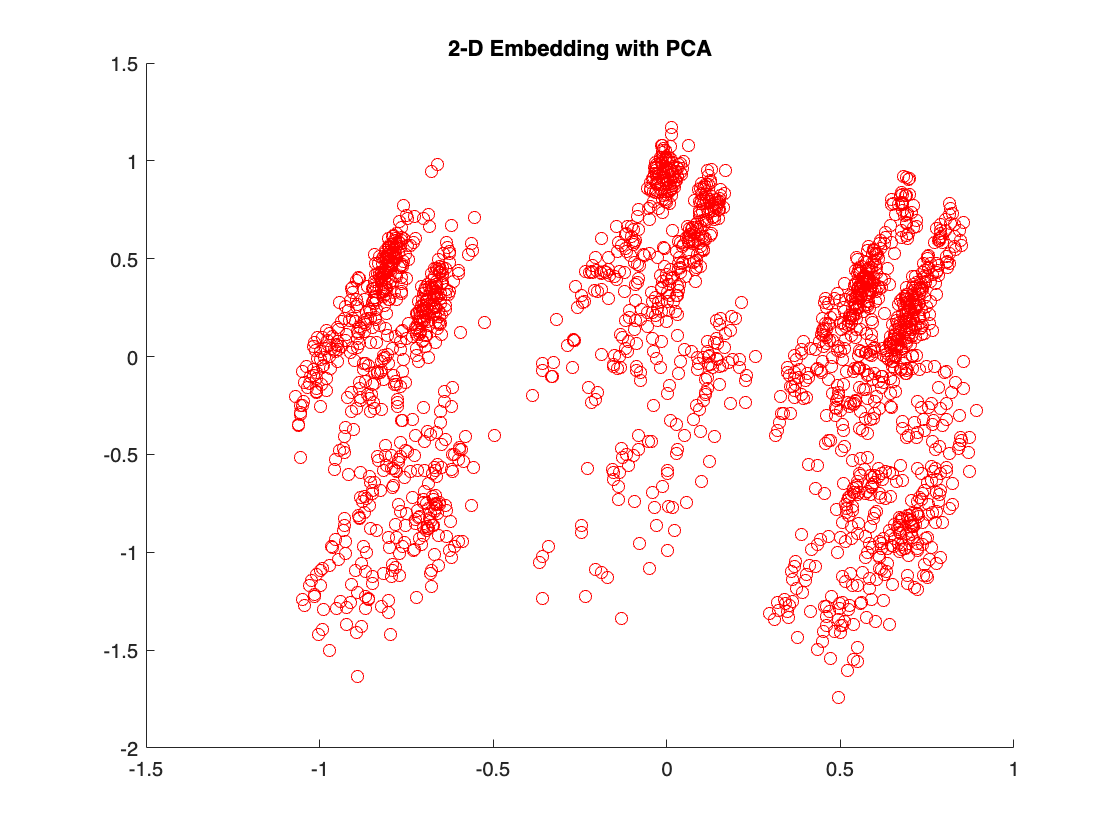

[coeff,score,latent] = pca(X);
figure
scatter(score(:,1),score(:,2), 'r')
title('2-D Embedding with PCA')

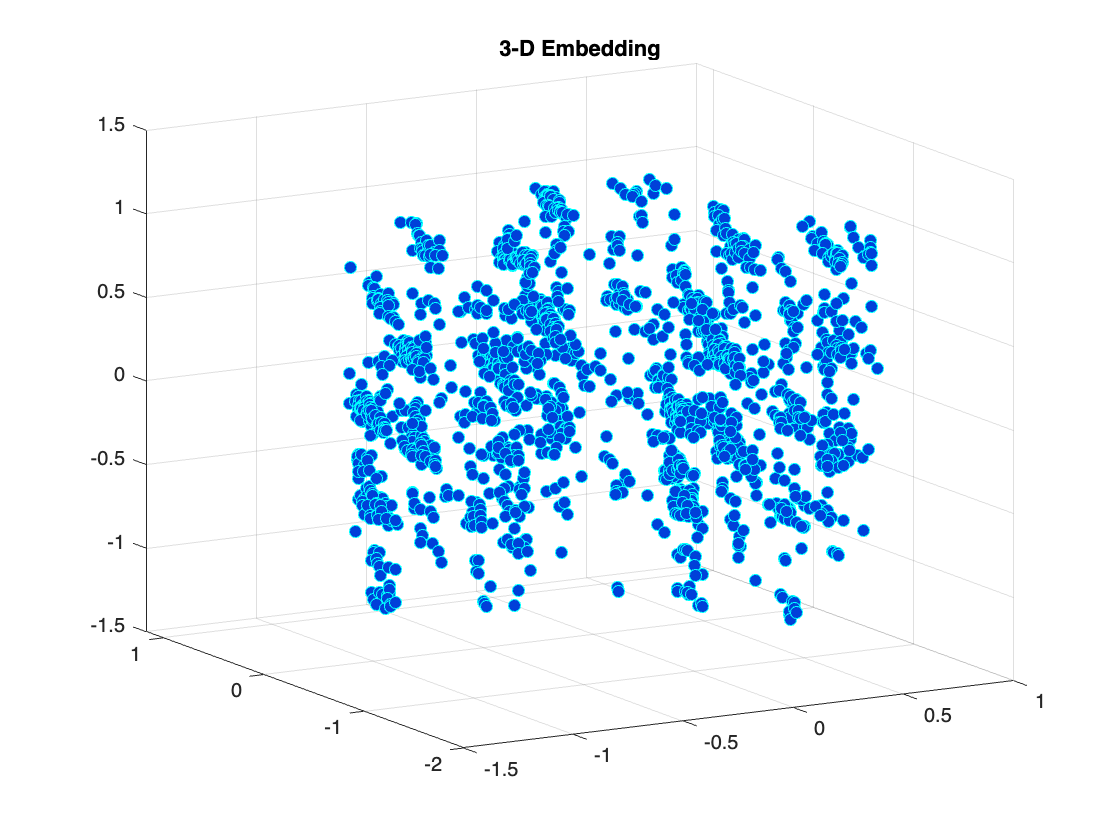

figure
scatter3(score(:,1),score(:,2),score(:,3),...
        'MarkerEdgeColor','c',...
        'MarkerFaceColor',[0 .25 .85])
title('3-D Embedding')
view(-30,15)

*HINTS*: you can try other dimensionality techniques ([https://it.mathworks.com/help/stats/dimensionality-reduction.html?s_tid=CRUX_lftnav](https://it.mathworks.com/help/stats/dimensionality-reduction.html?s_tid=CRUX_lftnav)), such as, for example, Indipendent Component Analysis ([https://it.mathworks.com/help/stats/rica.html](https://it.mathworks.com/help/stats/rica.html)) and compare the results. For those using Python, this is an interesting algorithm: [https://pypi.org/project/pacmap/](https://pypi.org/project/pacmap/). 

Do you see clusters around (with any of these dimensionality reduction techniques)? Explore and inspect the underlying data, try to understand if hypotetical clusters sounds meaningful or they look like mathematical artefacts.

### Clustering witk k-medoids

It's partition-based clustering.

By default, `kmedoids` uses squared Euclidean distance metric, so we need to use out custom distance function MixDistance.

In addition, the `kmedoids` function is NOT guaranteed to converge to a global minimum for the problem. So it is a good idea to cluster the problem a few times using the `'replicates'` (hyper)parameter. When `'replicates'` is set to a value, *n*, greater than 1, the k-medoids algorithm is run *n* times, and the best result is returned.

In the following code snippets:

- we cluster our data into different k cluster, k = 3, 4,...;

- we visualize clusters in a lower dimensional space for each value of k (remember all the caveats of visualization in applying dimensionality reduction techniques).

#### **3 clusters**

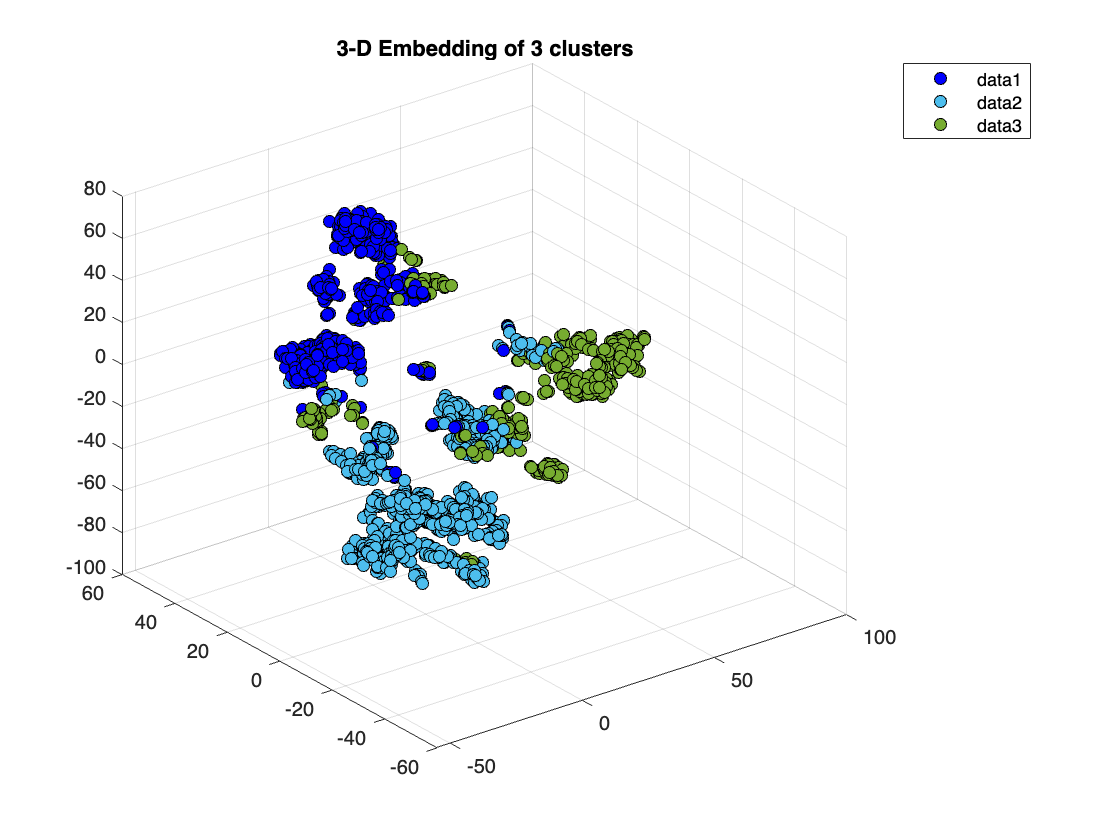

% qui vado a utilizzare algoritmo kmedoids con dentro valori di catergoria
% utilizzando come funzione di distanza quella modificata
[IDX3, C3, SUMD3, D3, MIDX3, INFO3] = kmedoids(X,3,'Distance', @MixDistance,'replicates',5);

% IDX3: Un vettore di indice che specifica l'assegnazione di ciascun punto nel dataset X a uno dei 3 cluster.
% C3: Una matrice contenente i centroidi dei cluster. Ogni riga di C3 corrisponde alle coordinate del centroide di uno dei 3 cluster.
% SUMD3: Un vettore contenente le somme delle distanze al quadrato tra ciascun punto e il suo centroide assegnato, utilizzato come misura della bontà del clustering.
% D3: Una matrice delle distanze tra i punti e i centroidi dei cluster.
% MIDX3: Un vettore che contiene l'indice del centroide più vicino a ciascun punto.
% INFO3: Una struttura contenente informazioni aggiuntive sull'esecuzione dell'algoritmo k-medoids.
figure
% Questo comando crea un diagramma di dispersione tridimensionale per il primo cluster. Vengono selezionati solo i punti nel dataset ridotto Y che sono stati assegnati al cluster 1 (IDX3==1). Le coordinate x, y e z di questi punti sono prese rispettivamente dalle colonne 1, 2 e 3 di Y. Il colore dei marker è impostato su blu.
scatter3(Y(IDX3==1,1),Y(IDX3==1,2),Y(IDX3==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
% Questo comando permette di sovrapporre più grafici sulla stessa figura.
hold on
scatter3(Y(IDX3==2,1),Y(IDX3==2,2),Y(IDX3==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX3==3,1),Y(IDX3==3,2),Y(IDX3==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('3-D Embedding of 3 clusters')
legend
hold off

#### **4 clusters**

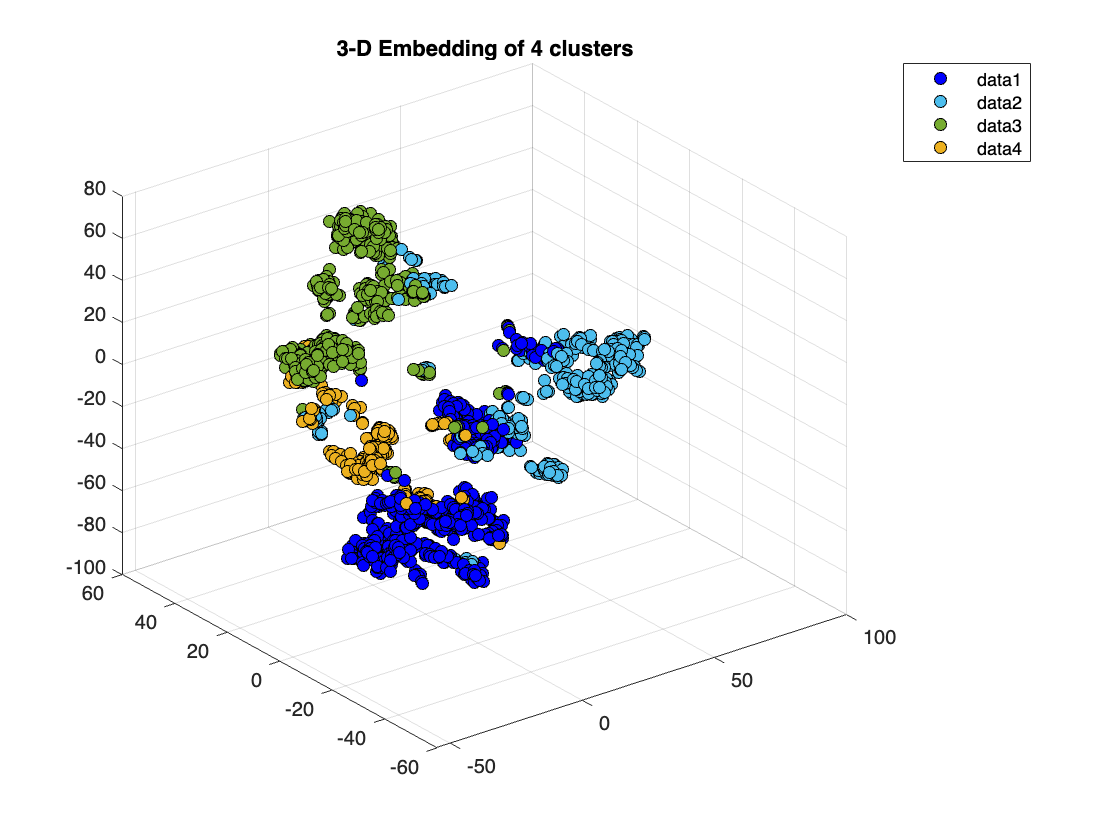

[IDX4, C4, SUMD4, D4, MIDX4, INFO4] = kmedoids(X,4,'Distance', @MixDistance,'replicates',5);

figure
scatter3(Y(IDX4==1,1),Y(IDX4==1,2),Y(IDX4==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX4==2,1),Y(IDX4==2,2),Y(IDX4==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX4==3,1),Y(IDX4==3,2),Y(IDX4==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX4==4,1),Y(IDX4==4,2),Y(IDX4==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
title('3-D Embedding of 4 clusters')
hold off
legend

#### **5 clusters**

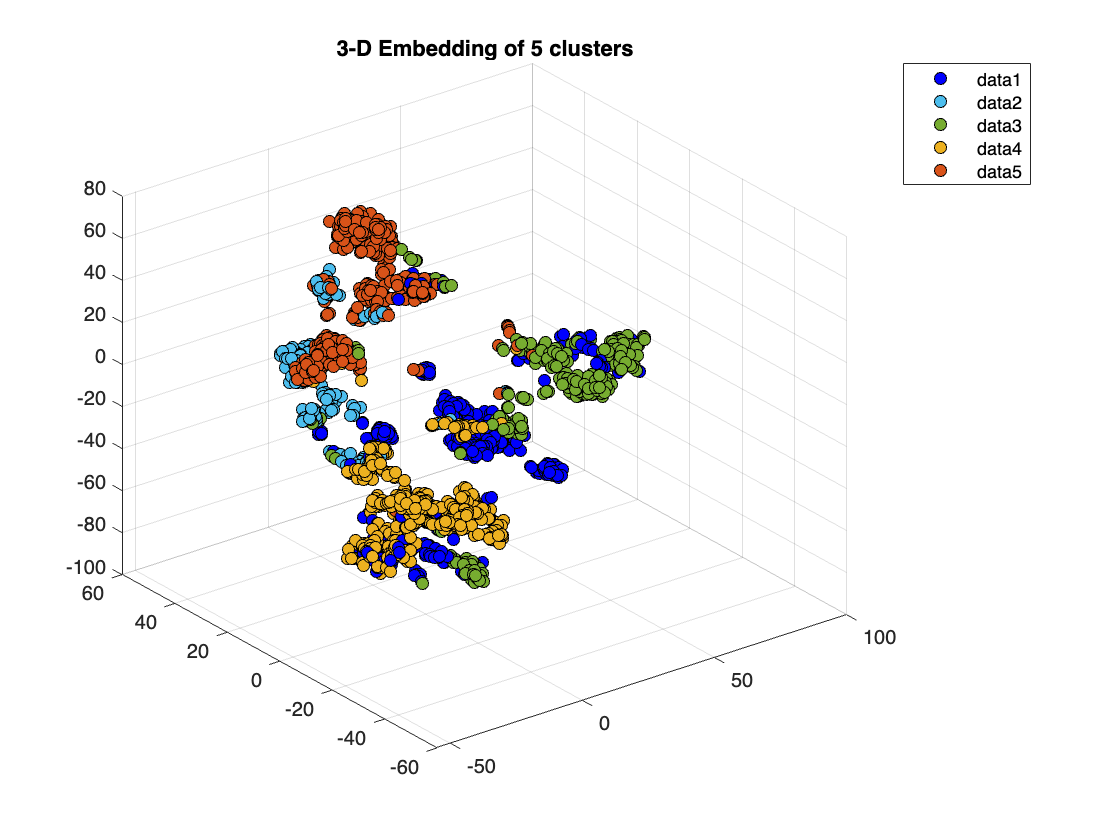

[IDX5, C5, SUMD5, D5, MIDX5, INFO5] = kmedoids(X,5,'Distance', @MixDistance,'replicates',5);

figure
scatter3(Y(IDX5==1,1),Y(IDX5==1,2),Y(IDX5==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX5==2,1),Y(IDX5==2,2),Y(IDX5==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX5==3,1),Y(IDX5==3,2),Y(IDX5==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX5==4,1),Y(IDX5==4,2),Y(IDX5==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX5==5,1),Y(IDX5==5,2),Y(IDX5==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
title('3-D Embedding of 5 clusters')
hold off
legend

#### 6 clusters

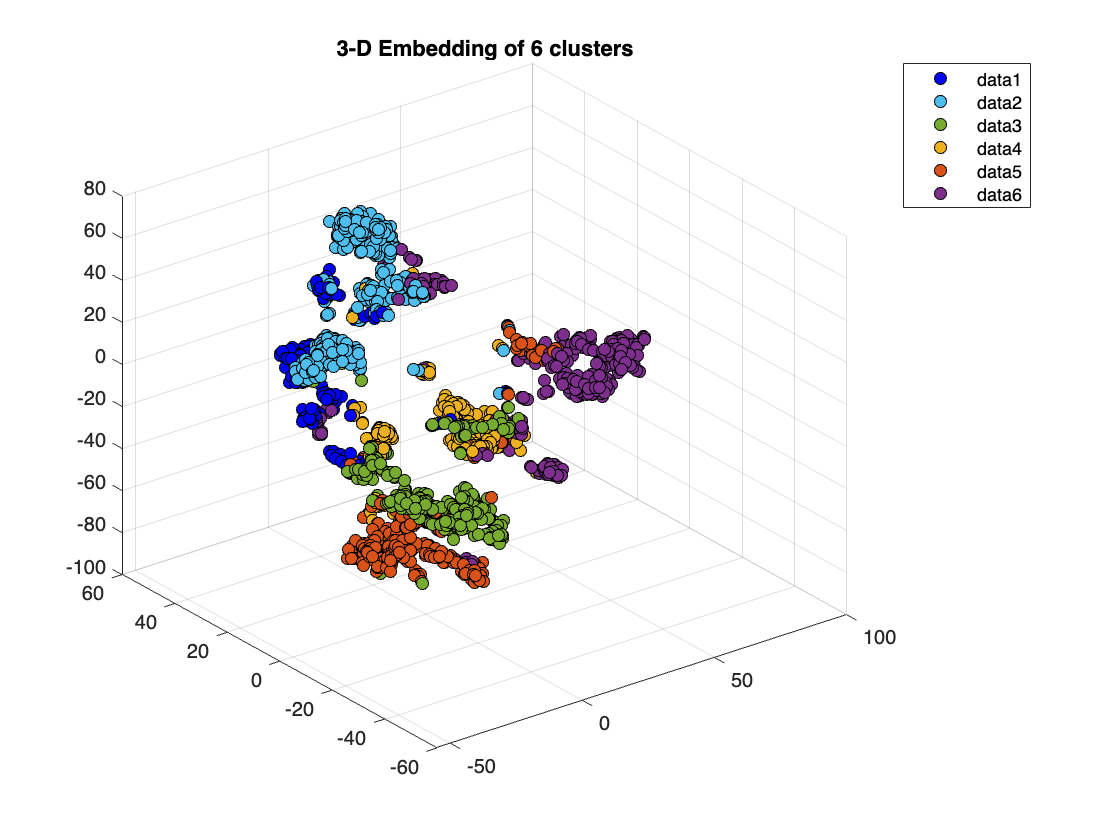

[IDX6, C6, SUMD6, D6, MIDX6, INFO6] = kmedoids(X,6,'Distance', @MixDistance,'replicates',5);

figure
scatter3(Y(IDX6==1,1),Y(IDX6==1,2),Y(IDX6==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX6==2,1),Y(IDX6==2,2),Y(IDX6==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX6==3,1),Y(IDX6==3,2),Y(IDX6==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX6==4,1),Y(IDX6==4,2),Y(IDX6==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX6==5,1),Y(IDX6==5,2),Y(IDX6==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(IDX6==6,1),Y(IDX6==6,2),Y(IDX6==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
title('3-D Embedding of 6 clusters')
legend
hold off

#### Clustering evaluation

Our goal is to determine how well the data fits into a particular number of clusters using different evaluation criteria.

**Calinski-Harabasz criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.calinskiharabaszevaluation-class.html)](https://it.mathworks.com/help/stats/clustering.evaluation.calinskiharabaszevaluation-class.html)).

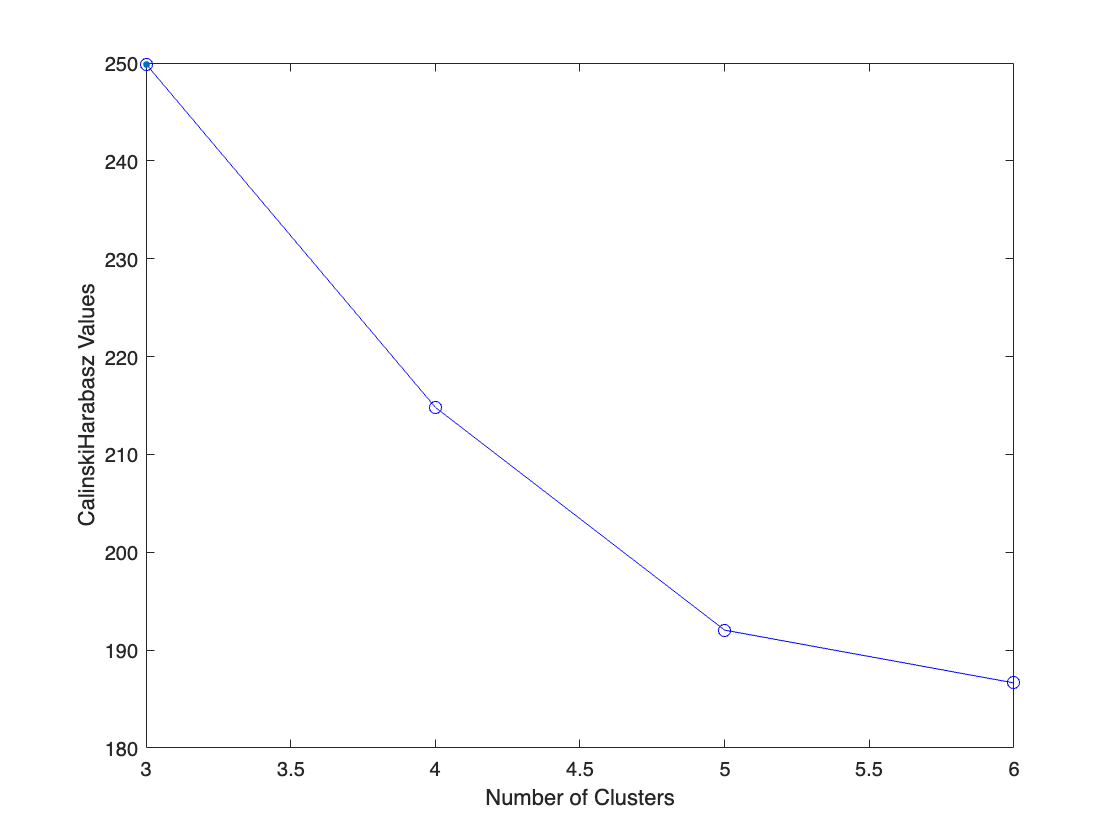

clust = [IDX3 IDX4 IDX5 IDX6];
% vado a comparare tutti i miei clustering con la funzione che mi dice la
% bontà del clustering c'è dentro anche il silutte e risulta con k = 3
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)

eva1

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1950
         InspectedK: [3 4 5 6]
    CriterionValues: [249.8956 214.8142 192.0456 186.6512]
           OptimalK: 3


The plot shows that the highest Calinski-Harabasz value occurs at ... clusters, suggesting that the optimal number of clusters is ...

**Davies-Bouldin criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.daviesbouldinevaluation-class.html](https://it.mathworks.com/help/stats/clustering.evaluation.daviesbouldinevaluation-class.html)).

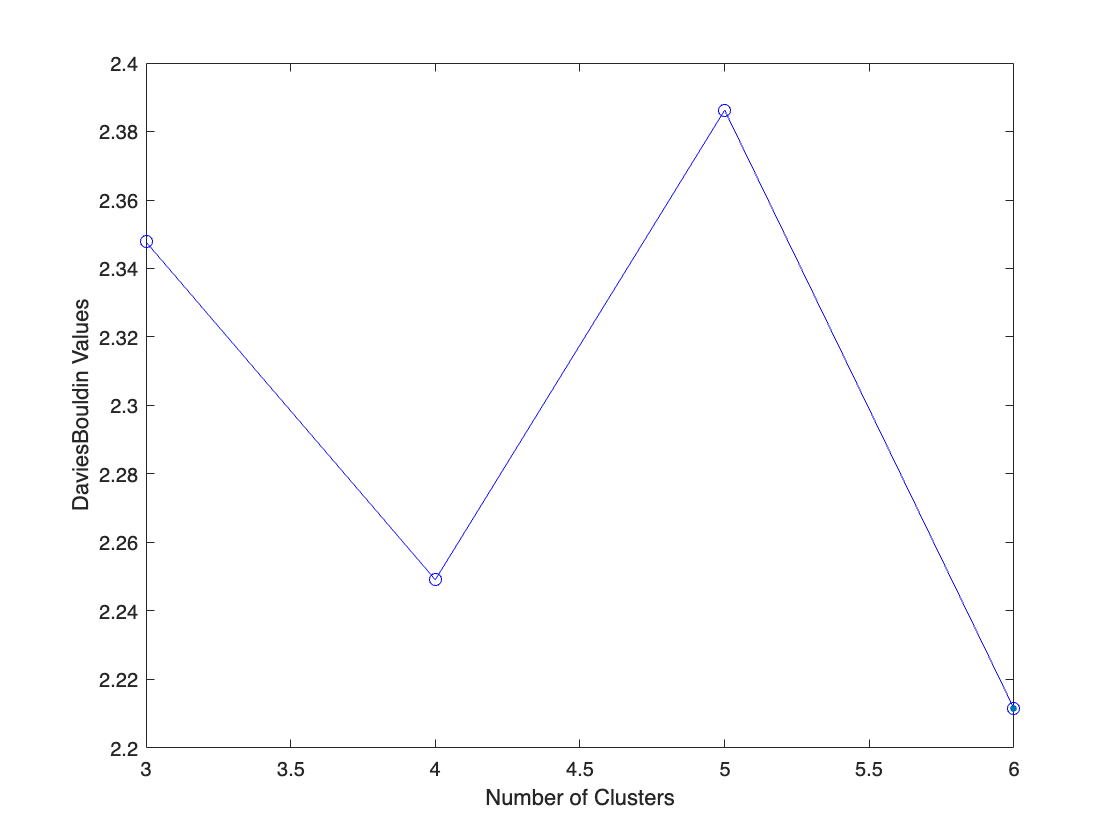

eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)

eva2

eva2 =   DaviesBouldinEvaluation with properties:

    NumObservations: 1950
         InspectedK: [3 4 5 6]
    CriterionValues: [2.3478 2.2491 2.3862 2.2115]
           OptimalK: 6


The plot shows that the lowest Davies-Bouldin value occurs at ... clusters, suggesting that the optimal number of clusters is ...

**Silhouette criterion** ([https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html](https://it.mathworks.com/help/stats/clustering.evaluation.silhouetteevaluation-class.html)).

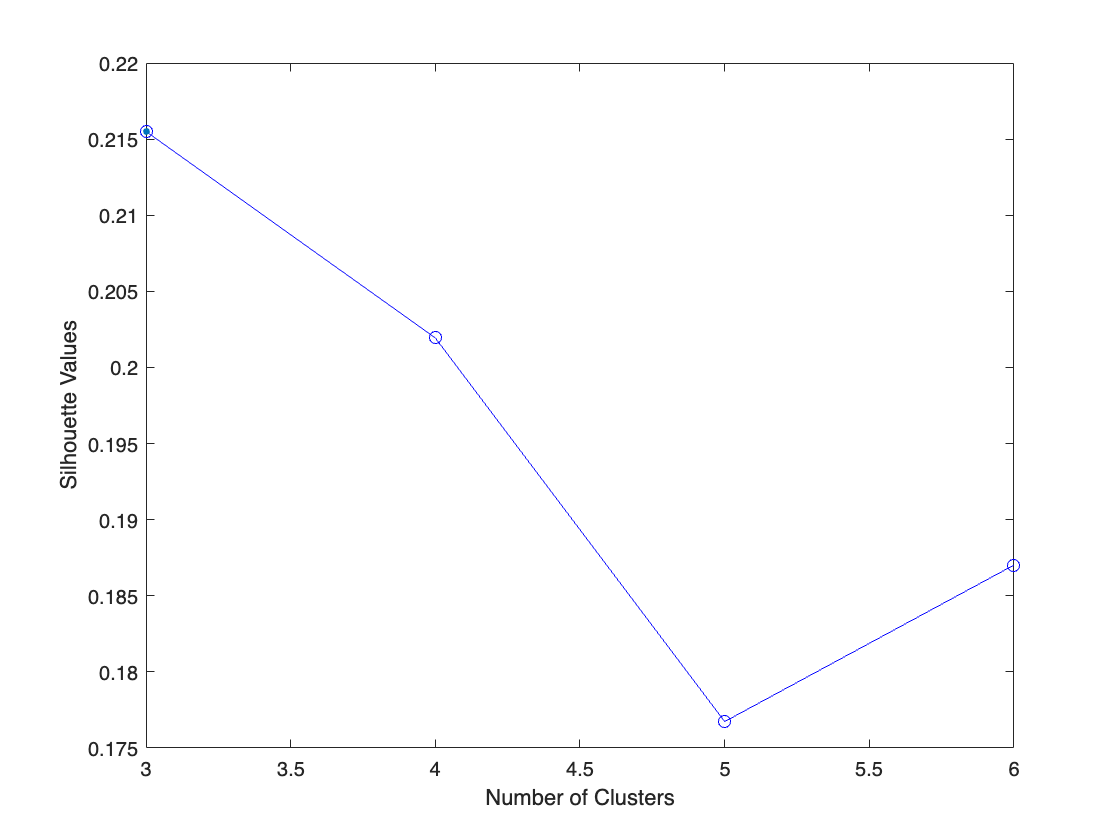

eva3 = evalclusters(X,clust,'silhouette', 'Distance', @MixDistance);
figure
plot(eva3)

eva3

eva3 =   SilhouetteEvaluation with properties:

    NumObservations: 1950
         InspectedK: [3 4 5 6]
    CriterionValues: [0.2155 0.2019 0.1767 0.1870]
           OptimalK: 3


The plot shows that the highest silhouette value occurs at ... clusters, suggesting that the optimal number of clusters is ...

Let's have a closer look at the silhouette of the most reasonable clusters hypothesis.

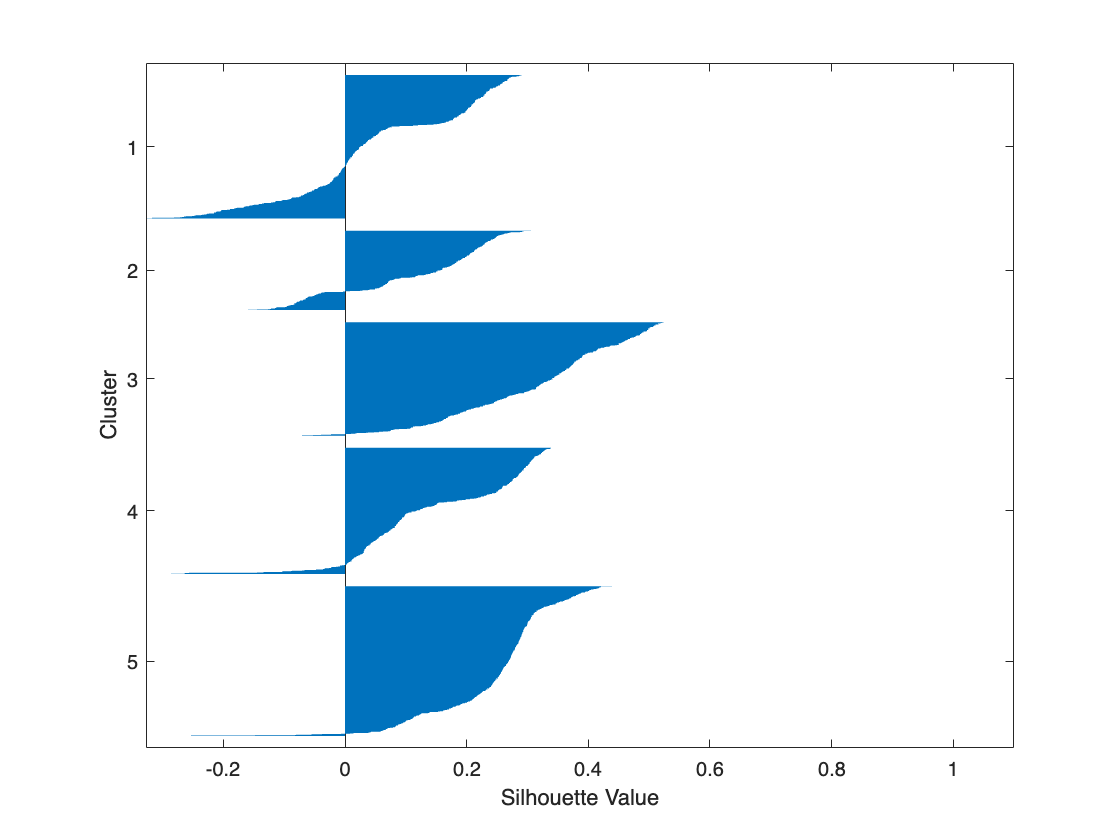

figure
silhouette(X,IDX5, @MixDistance);

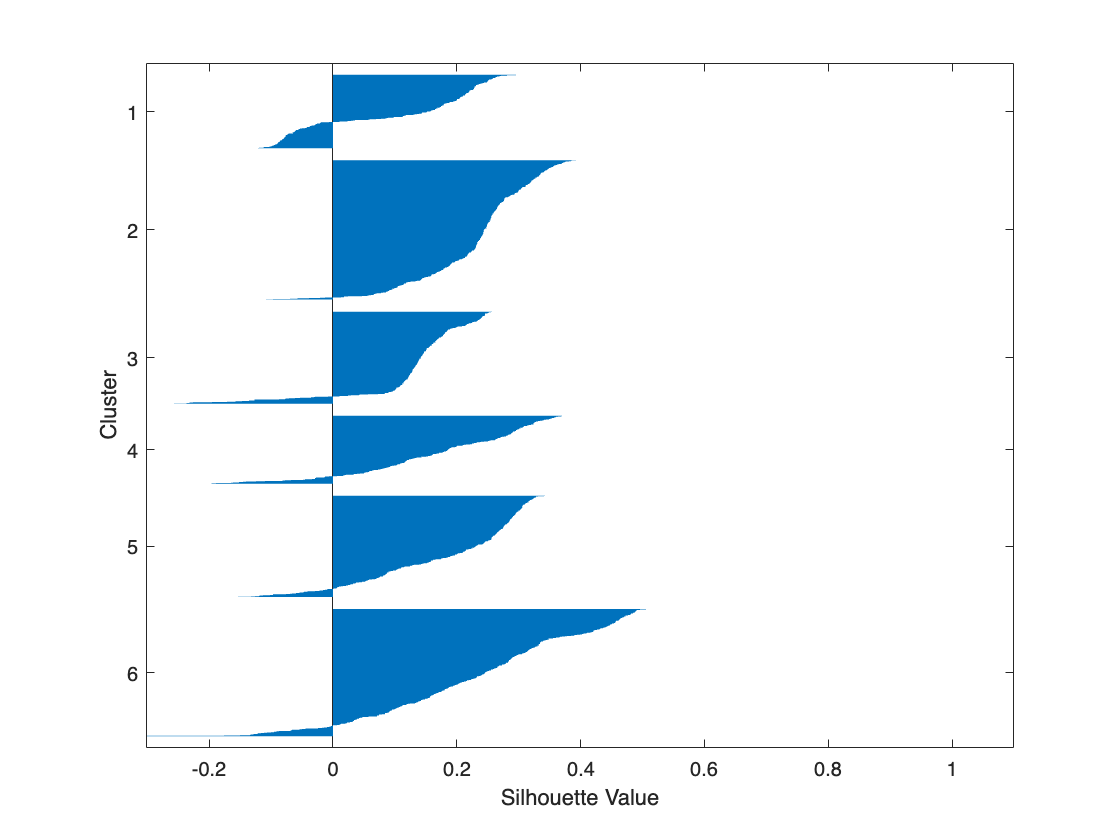

figure
silhouette(X,IDX6,@MixDistance);

#### Use of artificial data

In order to understand how a method works it is very useful to use artificial data that you create yourself, whose properties are known to you by definition (artificial data are useful in many other ways).

Compare the above result with an artificial "perfect" 2-D example (a mixture of 3 multivariate gaussians - i.e., bivariate gaussians), just to get the feeling...

rng('default');  % For reproducibility
% Artificial cluster 1
mu1 = [1 1];
sigma1 = [0.75 0.0; 0.0 0.8];
% Artificial cluster 2
mu2 = [6 6];
sigma2 = [0.3 0.3; 0.3 0.4];
% Artificial cluster 3
mu3 = [-3, -3];
sigma3 = [1.5 -0.4; -0.4 1.15];

NumArtificialClusters = 1000;

ArtificialX = [mvnrnd(mu1,sigma1,NumArtificialClusters);...
    mvnrnd(mu2,sigma2,NumArtificialClusters);...
    mvnrnd(mu3,sigma3,NumArtificialClusters)];

EvaArtificial = evalclusters(ArtificialX,'kmeans','silhouette','klist',[2:5])

EvaArtificial =   SilhouetteEvaluation with properties:

    NumObservations: 3000
         InspectedK: [2 3 4 5]
    CriterionValues: [0.8147 0.9040 0.7981 0.6492]
           OptimalK: 3


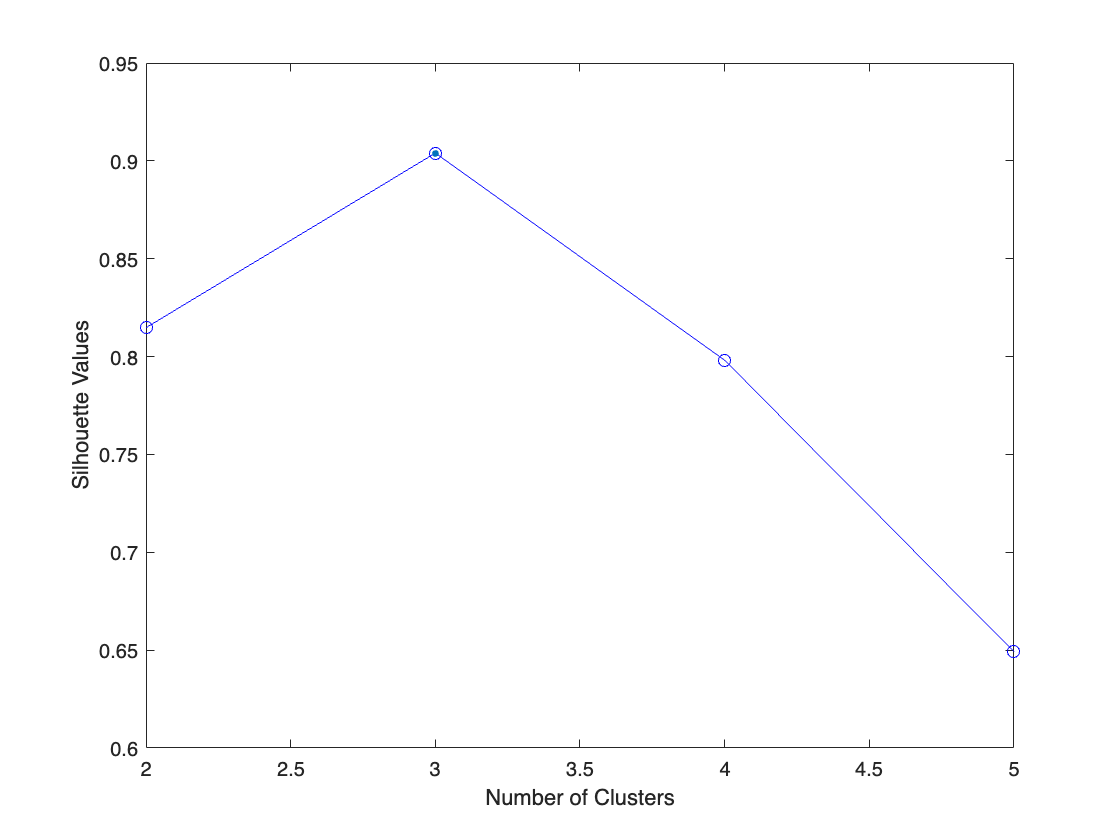

figure;
plot(EvaArtificial)

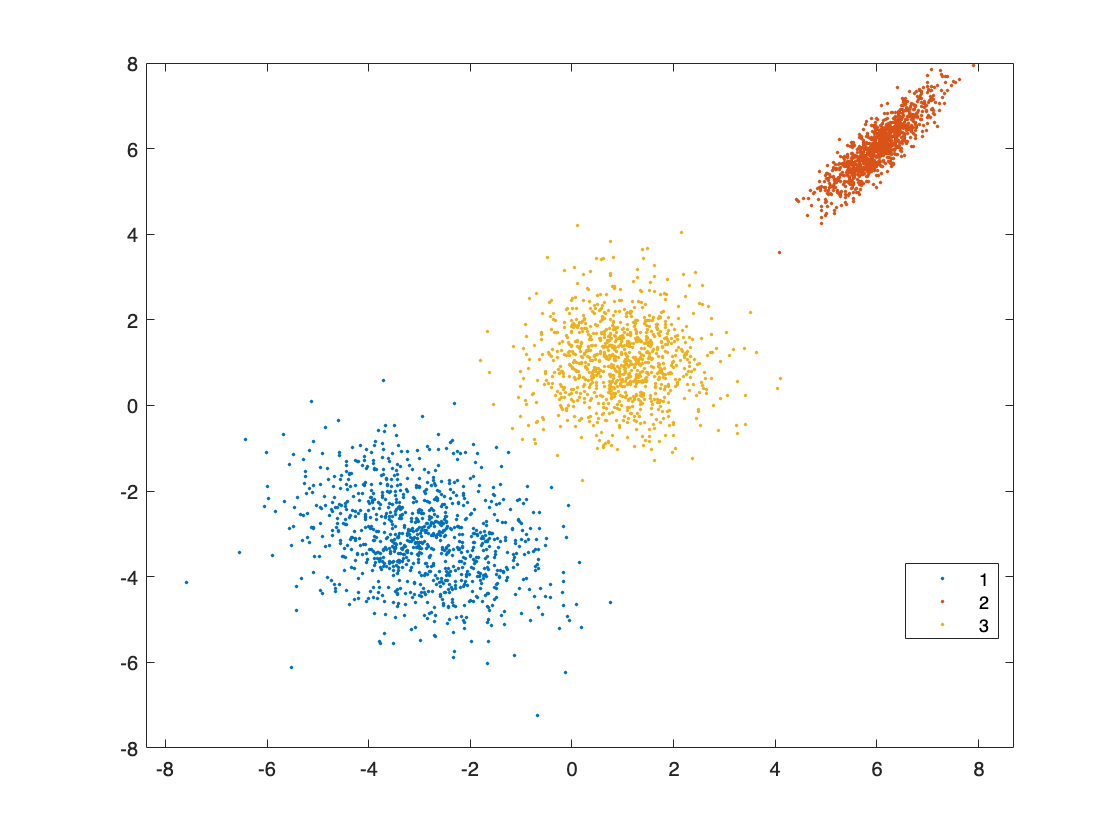


figure;
gscatter(ArtificialX(:,1),ArtificialX(:,2),EvaArtificial.OptimalY)

*HINT*: use artificial data changing the shape and the number of the clusters (e.g. change the parameters of the three bivariate gaussian distribution of this code snippet), and try different clustring techniques and evaluation criteria. 

### Clustering with DB-Scan

Let's try a completly different clustering approach - Density-based clustering: **DBSCAN** ([https://it.mathworks.com/help/stats/dbscan.html](https://it.mathworks.com/help/stats/dbscan.html)). The key intuition behind DBSCAN is that a point belongs to a cluster if it is close to many points from that cluster.

DBSCAN identifies arbitrarily shaped clusters and noise (outliers) in data. We can perform clustering on an input data matrix or on pairwise distances between observations, which is our case, and the function `dbscan`r returns the cluster indices and a vector indicating the observations that are core points (points inside clusters). Unlike other clustering methods, the DBSCAN algorithm does not require prior knowledge of the number of clusters (and clusters are not necessarily spheroidal). 

When it comes to arbitrary shaped clusters or detecting outliers, density-based techniques are more efficient, and can be used with categorical data, if we use the proper distance metrix - like we are supposed to do.

For a point to be assigned to a cluster, it must satisfy the condition that its epsilon neighborhood ([`epsilon`](https://it.mathworks.com/help/releases/R2021a/stats/dbscan.html#mw_8e9da8d6-2310-43e6-83ba-848b3f135fb7)) contains at least a minimum number of neighbors ([`minpts`](https://it.mathworks.com/help/releases/R2021a/stats/dbscan.html#mw_8f71b08a-185b-49d9-b224-3733d73ca4bd)). Or, the point can lie within the epsilon neighborhood of another point that satisfies the `epsilon` and `minpts` conditions.The DBSCAN algorithm identifies three kinds of points:

- Core point — A point in a cluster that has at least `minpts` neighbors in its epsilon neighborhood;

- Border point — A point in a cluster that has fewer than `minpts` neighbors in its epsilon neighborhood;

- Noise point — An outlier that does not belong to any cluster.

To select a value for `minpts`, consider a value > #features+1. We have about 30 features, but we don't want very small cluster.

A good strategy for estimating a value for `epsilon` is to generate a *k*-distance graph for the input data `X: f`or each point in `X`, we find the distance to the *k*th nearest point, and plot sorted points against this distance. The graph contains a knee, and the distance that corresponds to the knee is usually a good choice for `epsilon`, because it is the region where points start tailing off into "noise" territory.

- Il punto stesso deve avere almeno un certo numero minimo di punti vicini (minpts) all'interno del suo epsilon-vicinato (epsilon). Questo significa che il punto ha abbastanza punti vicini all'interno di una certa distanza (epsilon) per essere considerato parte del cluster.

- Il punto può giacere all'interno dell'epsilon-vicinato di un altro punto che soddisfa le condizioni di epsilon e minpts. In altre parole, anche se il punto stesso non ha abbastanza punti vicini per soddisfare la condizione, se è abbastanza vicino ad altri punti che soddisfano tali condizioni, può comunque essere assegnato al loro cluster.

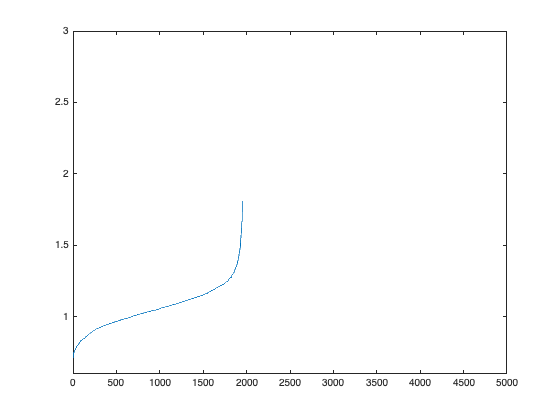

minpts = 100;
Distance = MixDistance(X,X);
orderedDistance = sort(Distance, 'ascend');
cut = orderedDistance(minpts,:);
altro = sort(cut); 
plot(altro);

xlim([0 5000])
ylim([0.60 3])

The knee appears to be around ... we set the value of epsilon to ...

epsilon = 2.5;
[DBSCANidx, corepts] = dbscan(Distance,epsilon,minpts,'Distance','precomputed');
nDBSCANCluster = unique(DBSCANidx)

nDBSCANCluster = 1

So we find ... clusters and one group of outliers (nDBSCANCluster = -1).

Visualizing clusters in 2-D.

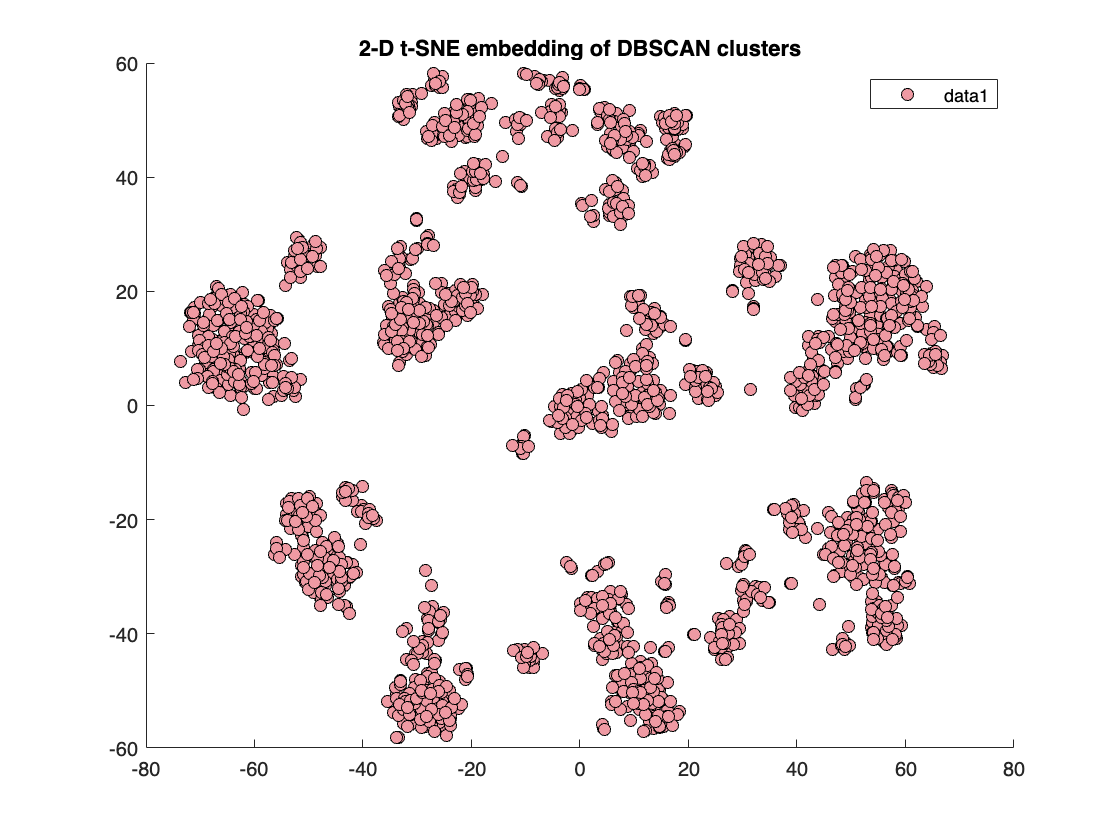

Y = tsne(X,'Algorithm','exact','Distance', @MixDistance,'NumDimensions', 2);
figure
for i = 1:size(nDBSCANCluster,1)
    pointer = nDBSCANCluster(i);
    scatter(Y(DBSCANidx==pointer,1),Y(DBSCANidx==pointer,2),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colours
    hold on
end
title('2-D t-SNE embedding of DBSCAN clusters')
legend
hold off

Visualizing in 3-D

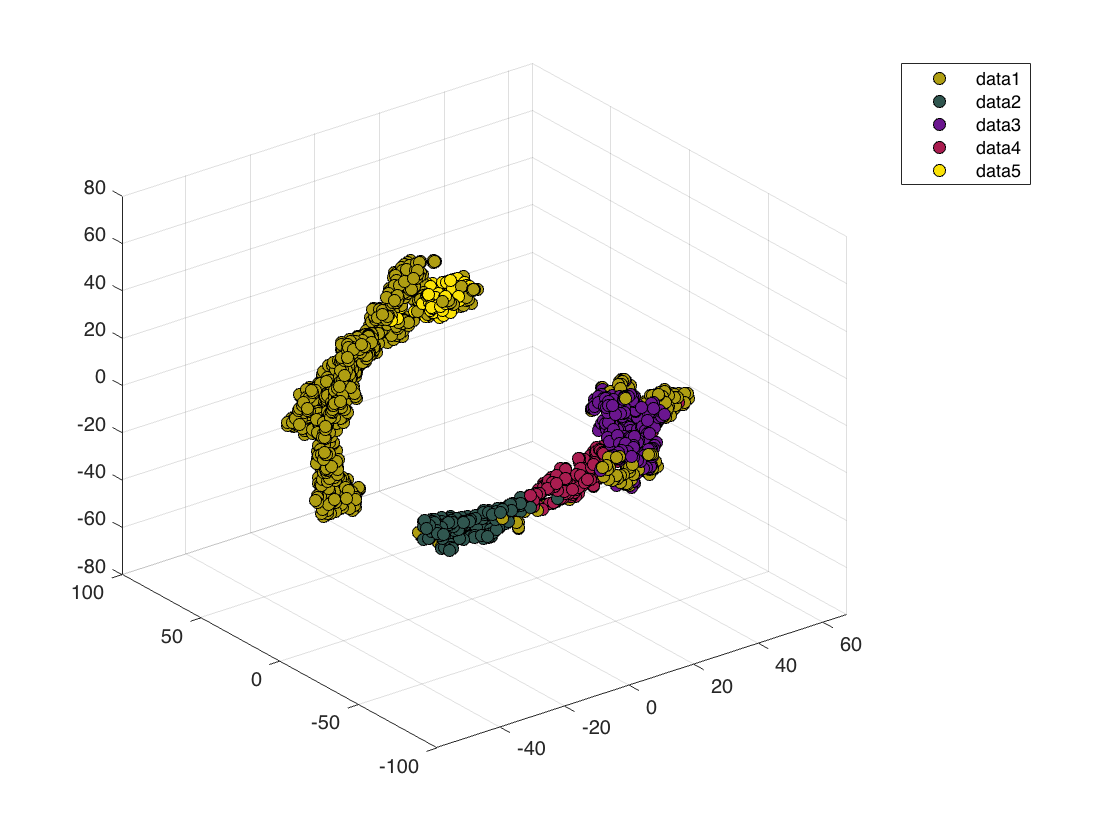

Y = tsne(X,'Algorithm','exact','Distance', @MixDistance,'NumDimensions',3);
figure
for i = 1:size(nDBSCANCluster,1)
    pointer = nDBSCANCluster(i);
    scatter3(Y(DBSCANidx==pointer,1),Y(DBSCANidx==pointer,2),Y(DBSCANidx==pointer,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colors
    hold on
end
hold off
legend

### Spectral clustering

Spectral clustering is a graph-based algorithm for partitioning data points, or observations, into arbitrarly shaped *k* clusters. The technique involves representing the data in a low dimension, where hopefully clusters in the data are more widely separated, and this low dimension is based on the eigenvectors corresponding to the *k* smallest eigenvalues of a Laplacian matrix. The function [`spectralcluster`](https://it.mathworks.com/help/releases/R2021a/stats/spectralcluster.html) performs clustering on an input data matrix or on a [similarity matrix](https://it.mathworks.com/help/releases/R2021a/stats/spectralcluster.html#mw_319da951-f871-482c-b648-5056f4ebff46_sep_shared-SimilarityMatrix) derived from the data. Note: `spectralcluster` requires you to specify the number of clusters.

#### Compute distance and similarity

So we calculate the distance and we transform it in a similarity matrix - we convert the distances to similarity measures using a kernel transformation.

Distance = MixDistance(X,X);
Similarity = exp(-Distance.^2); % kernel transformation
issymmetric(Similarity); % check symmetry
nCluster = 3;
[SpectralIdx, V, D] = spectralcluster(Similarity,nCluster,'Distance','precomputed','LaplacianNormalization','symmetric');

The number of zero eigenvalues of a Laplacian matrix is a first estimate of the number of clusters in your data (but not always...). 

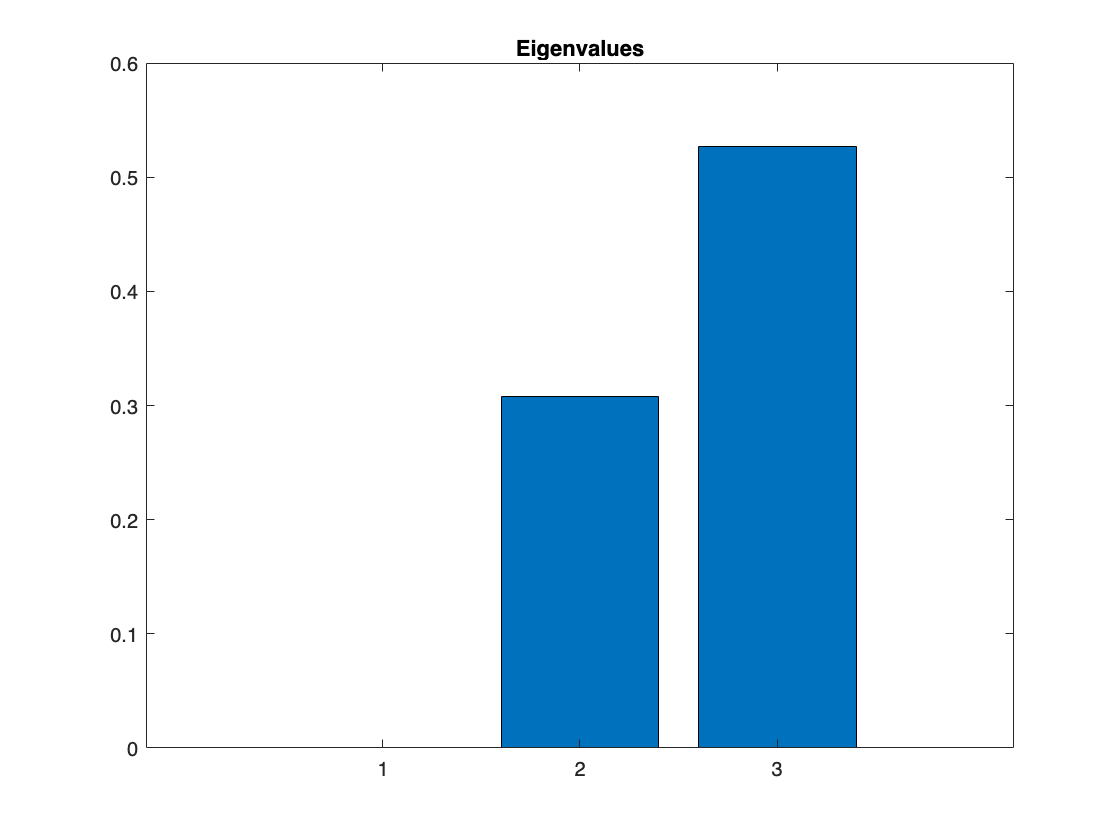

figure
bar(D)
title('Eigenvalues')

*HINTS*: try different clustering methods and see what happens, using all the methdos we have see so far.

For example you might try a simple **Nearest Neighbor search** ([https://it.mathworks.com/help/stats/nearest-neighbors-1.html](https://it.mathworks.com/help/stats/nearest-neighbors-1.html)) that locates the k-nearest neighbors within a specified distance to query data points, based on the specified distance metric we have used so far, MixDistance. l-NN is considered a Supervised Machine learning algorithm. So this improper "clustering" simply refers to getting the nearest neighbours of a given point - a point, not necessarily in the data set, that you might have chosen based on business experience supported by data evidence - either (1) by taking all the neighbours in some ball around this point with a given cutoff radius or (2) by taking the k nearest neighbours and returning them as the cluster.

Compare the results. Try also methods that shouldn't work with these data (e.g. not suitable for categorical variables), and see what happens: understanding the effect of the model specification error is key, doing applied Machine Learning, as the "perfect model" doesn't exist. 

### Inspecting clusters

It's key to analyze clusters from the business perspective, trying to understand if they are meaningful. (It takes time. But it can be fun.)

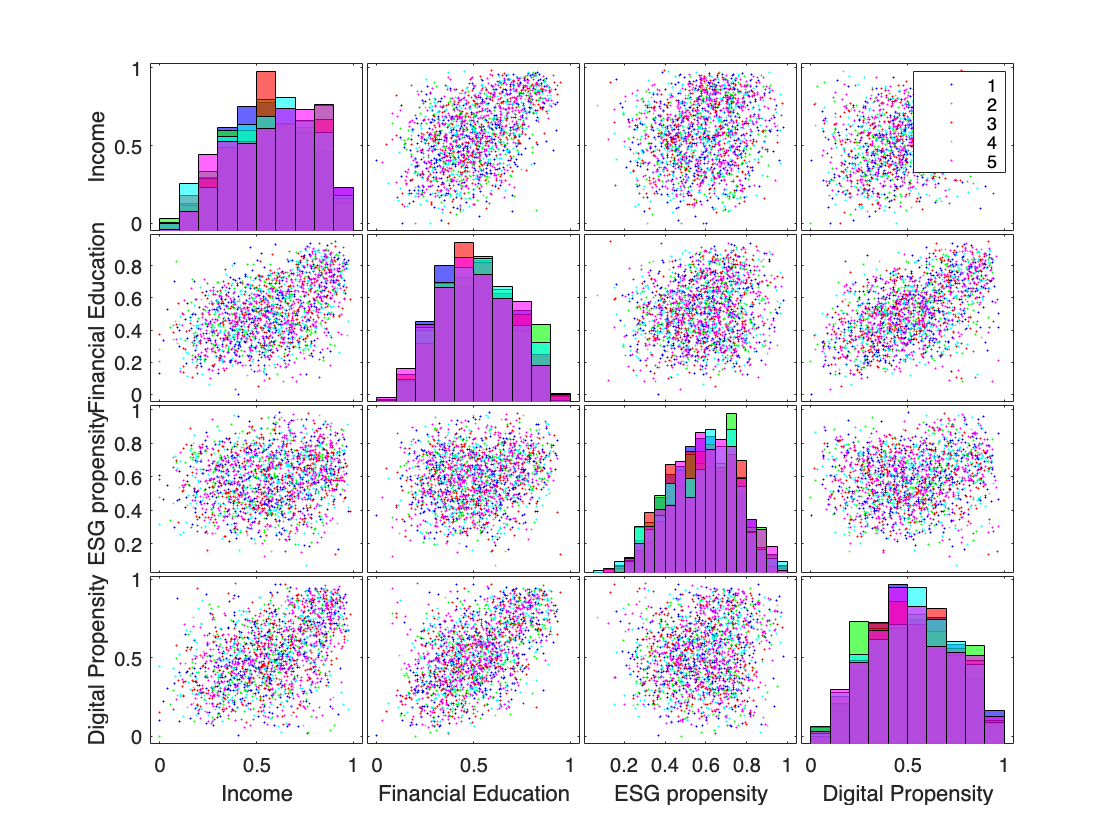

Data4Plot = [BankClients.Income  BankClients.FinEdu  BankClients.ESG  BankClients.Digital];
xnames = {'Income', 'Financial Education', 'ESG propensity', 'Digital Propensity'};
gplotmatrix(Data4Plot(1:1950,:),[],IDX5, [],[],[],[],'grpbars', xnames)

ClusterCardinality = grpstats(X(:, 1),IDX5, 'numel');
ClusterCardinality = ClusterCardinality/sum(ClusterCardinality)

ClusterCardinality =     0.2344
    0.1297
    0.1851
    0.2062
    0.2446


ClusterMedian = 100*grpstats(X(:,12:end),IDX5, @median)

ClusterMedian =    59.2105   20.0000   58.8721   56.0156   45.8234   52.7459   57.8442   50.2031   57.1136   45.4500   49.0798   56.8403
   55.2632   40.0000   56.2718   57.9581   46.8969   50.0136   55.4323   50.7490   57.2952   39.7567   40.8265   58.5006
   43.4211   20.0000   83.2415   82.6557   58.6326   76.2095   69.7890   81.3583   77.1361   70.0952   76.5084   64.7021
   61.8421   40.0000   50.6330   51.6081   38.9861   43.8635   56.1365   46.3878   56.9312   36.9912   32.8914   51.7402
   68.4211   40.0000   51.2899   52.6382   40.6062   45.1169   53.7403   45.1460   53.9818   34.8085   35.3530   53.3261


*HINTS*: try to understand how clusters are made, if they "make business sense". This means, for example:

- Exploring average statistics of each cluster (see above);

- Looking at frequency distributions for the features/variables for each cluster, or scatter plots (see above);

- Maybe you want to eliminate some variables, which you think are uninteresting, and then perform the cluster analysis again, refining the previosu work;

- Or, you might still want to include seemingly uninteresting features, because they make sense from a financial marketing point of view;

- In the end, try to get explainable clusters; a good way is to try to describe them with a name, a short sentence - to do so, see if they are more women or men, more or less wealthy, more or less young, etc. etc. (remember, most variables are normalized, so basically you have ordered statistics).